signalPath = '.\signals\L.mat';

addpath 'C:\Users\HP\Downloads\DSP Project\hmb\Applications\SASS'

disp("Running GASS for signal @ " + signalPath);

Running GASS for signal @ .\signals\V.mat


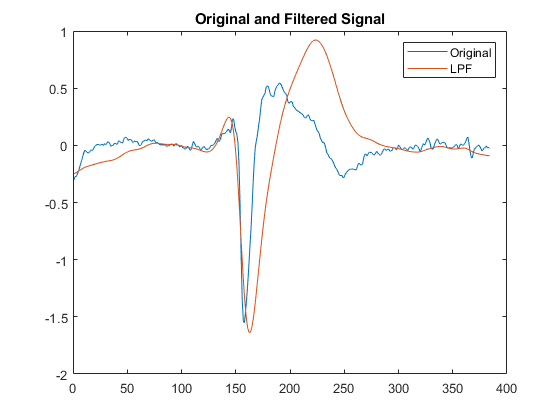


% Load the Raw ECG Signal
original = load(signalPath).var;
original = original(:);

% Mean normalization
y = original - mean(original);

N = length(original);
d = 2;                          
fc = 0.04;                      
K = 2;                          

[A, B] = ABfilt(d, fc, N, K);

H = @(x) A\(B*x);   % Zero-phase High Pass Filter
L = @(x) x - H(x);  % Zero-phase Low Pass Filter

low_pass_output = L(y);

% Baseline wander Removal
original = baseline_remove(original);

figure;
plot(original);
hold on
plot(low_pass_output);
title('Original and Filtered Signal');
legend({'Original', 'LPF'});

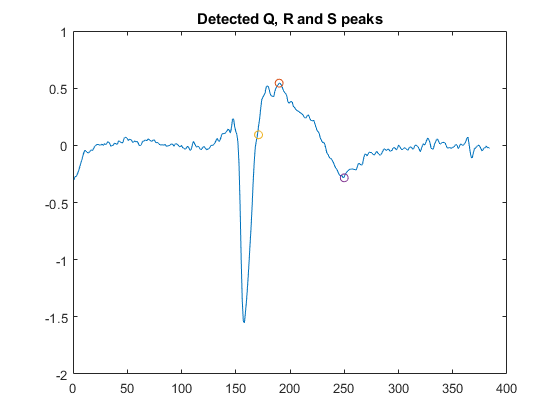


% Peaks from Original

search_width = 60;
search_width_q = 20;        

%R
[o_pks, o_locs] = max(original);

if o_locs-search_width_q <= 0
    search_width_q = o_locs - 1;
end

%Q       
[o_pks2, o_locs2] = max(-original(o_locs - search_width_q : o_locs));
o_locs2 = o_locs2 + o_locs - search_width_q;

if isempty(o_locs2)
    o_locs2 = round(o_locs - (search_width_q)/2);
    o_pks2 = original(o_locs2);
end 
        
if o_locs+search_width > N
    search_width = N - o_locs - 1;
end        

%S
[o_pks3, o_locs3] = max(-original(o_locs : o_locs + search_width));
o_locs3 = o_locs3 + o_locs;

if isempty(o_locs3)
    o_locs3 = round(o_locs + (search_width)/2);
    o_pks3 = original(o_locs3);
end 

figure;
plot(1 : length(original),original,o_locs,o_pks,'o');
hold on
plot(o_locs2,-o_pks2,'o', o_locs3,-o_pks3,'o');
title('Detected Q, R and S peaks');

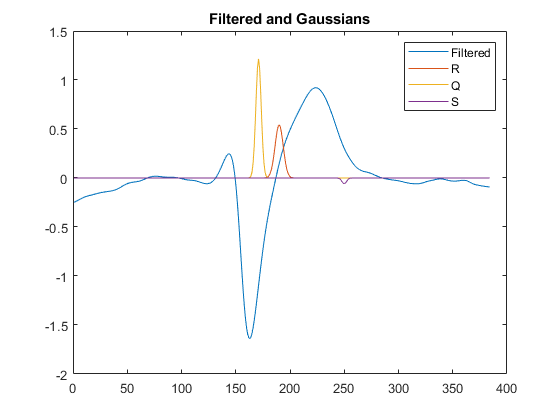


% Peaks from Filtered signal

%R
[pks, locs, width1, prom] = findpeaks(original ,'WidthReference','halfheight');

%Q and S
[pks2, locs2, width2, prom2] = findpeaks(-original, 'WidthReference','halfheight');

[~, ix_r] = min(abs(locs - o_locs));
[~, ix_q] = min(abs(locs2 - o_locs2));
[~, ix_s] = min(abs(locs2 - o_locs3));

widths = [];
widths(1) = width1(ix_r);
if widths(1) == 0 
    widths(1) = 3.75;
end
widths(2) = width2(ix_q); 
if widths(2) == 0 
    widths(2) = 3.75;
end
widths(3) = width2(ix_s);
if widths(3) == 0 
    widths(3) = 3.75;
end

for count = 1 : length(widths)
    if widths(count) > 0 && widths(count) < 0.1
        widths(count) = widths(count) / 5.00;
    elseif widths(count) >= 0.1 && widths(count) < 0.25
        widths(count) = widths(count) / 4.500;
    else
        widths(count) = widths(count) / 3.75;
    end
end

y={};

ratio_rq = o_pks/o_pks2;
ratio_rs = o_pks/o_pks3;

y{1} =  1  * o_pks  * gaussmf(1:N,[sqrt(widths(1)/2) o_locs])';
y{2} = -1  * (((low_pass_output(o_locs) + o_pks)/ratio_rq) - abs(low_pass_output(o_locs2))) * gaussmf(1:N,[sqrt(widths(2)/2) o_locs2])'; %o_pks2
y{3} = -1  * (((low_pass_output(o_locs) + o_pks)/ratio_rs) - abs(low_pass_output(o_locs3))) * gaussmf(1:N,[sqrt(widths(3)/2) o_locs3])'; %o_pks3
         
y{1} =  1  * o_pks  * gaussmf(1:N,[widths(1) o_locs])';
y{2} = -1  * (((low_pass_output(o_locs) + o_pks)/ratio_rq) - abs(low_pass_output(o_locs2))) * gaussmf(1:N,[widths(2) o_locs2])'; %o_pks2
y{3} = -1  * (((low_pass_output(o_locs) + o_pks)/ratio_rs) - abs(low_pass_output(o_locs3))) * gaussmf(1:N,[widths(3) o_locs3])'; %o_pks3

sass_sig = low_pass_output + y{1} + y{2} + y{3};    


figure;
plot(low_pass_output);
hold on
plot(y{1});
hold on
plot(y{2});
hold on
plot(y{3});
title('Filtered and Gaussians');
legend({'Filtered', 'R', 'Q', 'S'});

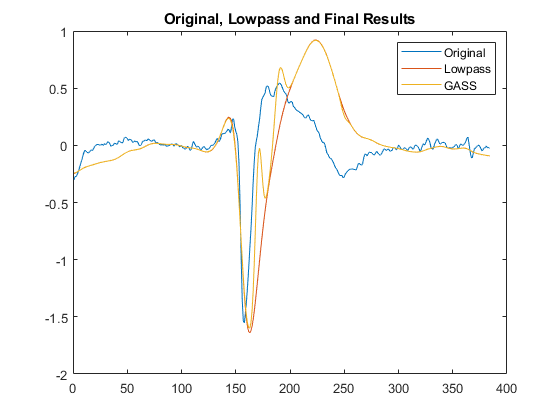


gass_result = movmean(low_pass_output + y{1} + y{2} + y{3}, 5);

figure;
plot(original);
hold on
plot(low_pass_output);
hold on
plot(gass_result);
title('Original, Lowpass and Final Results');
legend({'Original', 'Lowpass', 'GASS'});